# 14. Deskewing 2 Channels in the Frequency Domain

© B. Rasnow 3 Jun 25

## Introduction

In the previous chapter we addressed the systematic temporal shift between A0 and A1 in our sampled data. We used MATLAB's `spline` to interpolate and "deskew" A1 to simulate temporal alignment or concurrency with A0. The algorithm implemented in `spline` is somewhat akin to `polyfit`, fitting adjacent points to a cubic polynomial and then `polyval` to interpolate the results. The locality of this algorithm works best where the adjacent data is "smooth" with low noise, but it tends to underestimate peaks in the data that are sampled more sparsely at high frequencies. This document explores an alternative algorithm for deskewing data in the Frequency Domain. One advantage we'll see is this isn't based on local temporal information but instead weights the entire data set. We'll conclude by quantitatively comparing the two algorithms for sine waves of various frequencies. 

Shifting a sine wave in time is equivalent to adding phase: $cos(\omega (t+\Delta t)) = Re(e^{j\omega (t+\Delta t))}) = Re(e^{j\omega t}e^{j\omega \Delta t})$. So time shifting (by a constant $\Delta t$) in the frequency domain is done by multiplying each (complex) frequency component $A(\omega$) by a phasor $e^{-j\omega\Delta t}$ [1]. Even though each frequency component of the signal must be multiplied by a different phasor, time shifting is mathematically much simpler in the frequency domain! If you doubt me, `>> edit spline` and try to explain what's going on inside that onion.

## Simulating simple data

I'm not smart and confident enough to just write down the correct equations and coefficients in MATLAB, so I simulated simple, compact data: a square wave of period 10 samples, and A1 shifted 1 sample relative to A0: 

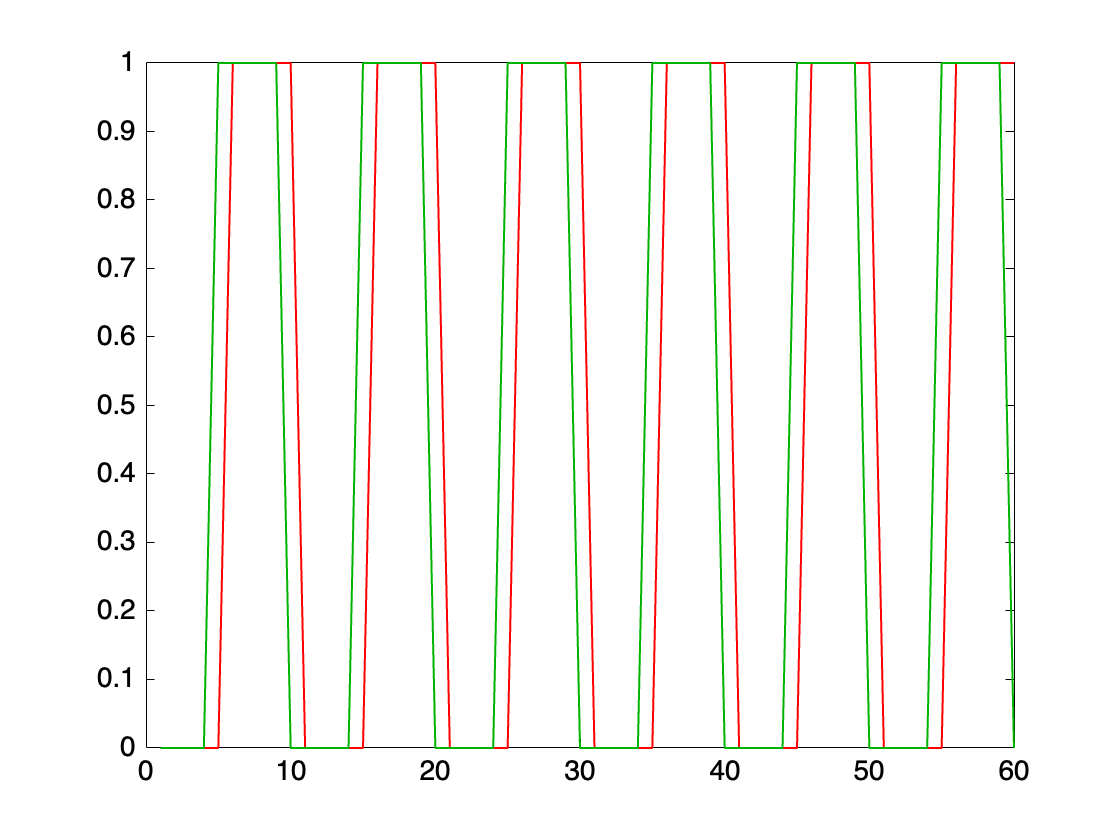

npds = 6; % number of periods
a = repmat([zeros(5,1); ones(5,1)],npds,1);
data = [a a([2:end 1])]; % [npds shifted_npds]
plot(data)

        Figure 1. Simulated square waves with a 1 sample shift.

 We expect $\Delta t = 1 \texttt{ sample} * \frac{2\pi \texttt{ radians}}{10 \texttt{ samples}}$ and the phasor argument should increase with frequency, i.e., $\Delta \phi = \omega * \Delta t$ (this formula *is* the definition of $\omega \equiv$$\frac{d\phi}{dt}$ = rate of change of phase). Converting this to a discrete phase shift vector, several trials led to: 

fd = fft(data);
dph = (0:length(data)-1)' * 2 * pi / 10 / npds;
phasor = exp(-1j * dph);
fd2 = [fd fd(:,2) .* phasor];
rad2deg(angle(fd2(7:12:end,:))) 

ans =   108.0000  144.0000  108.0000
  144.0000 -108.0000  144.0000
  180.0000         0 -180.0000
 -144.0000  108.0000 -144.0000
 -108.0000 -144.0000 -108.0000


The first column are phases of the odd harmonics of simulated A0 square wave, column 2 are phases of the 1-sample shifted square wave A1, and column 3 is phase shifted A1 ideally the same as A0. The first row is the phase of the square wave ([0 0 0 0 0 1 1 1 1 1 0 0 ...] apparently 90+18 degrees, or 90 + 1/2 a time sample from a cosine -- each time sample = 360 degrees / 10 samples = 36 degrees). ans(1,2) = 144 has 36 degrees more phase resulting from its 1 sample shift, and after phasor multiplication ans(1,3) it's initial phase was reconstructed. 

The 2nd row is the 3rd harmonic, so the 1 sample time shift is 3*36 degrees added to the initial phase of ans(2,1) = 252 degrees or equivalently (as Fourier computed it), -108 degrees, and phasor multiplication brought it back to its original `ans(2,1)=ans(2,3)`. 

The 3rd row is the 5th harmonic, with a phase shift of 5*36 = 180 degrees (= -180 degrees) ... All phase shifts are as expected. 

Let's take the Fourier shifted data (column 3) back to the time domain: 

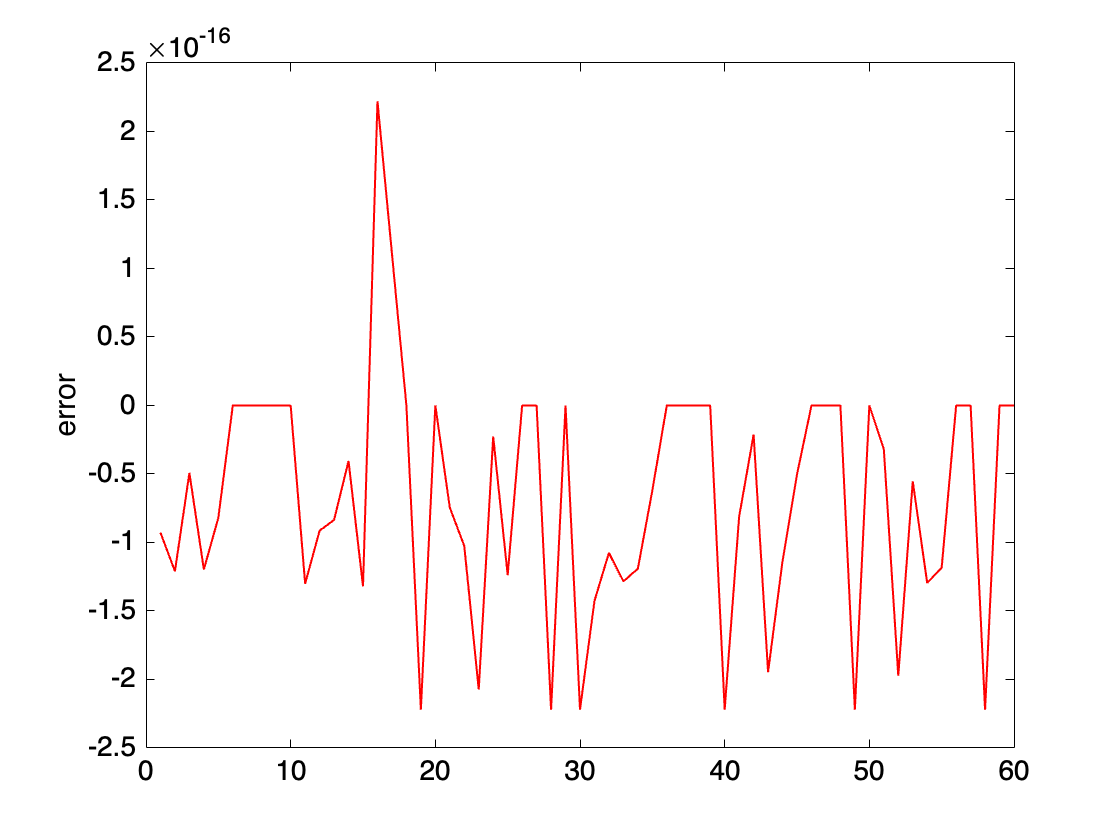

fshiftedA1 = abs(ifft(fd2(:,3)));
plot(a - fshiftedA1); ylabel('error')

        Figure 2. Difference between square wave and Fourier unshifted shifted square wave is 1e-16, a perfect correction within ~the error of floating point numbers. 

## arddeskew.m

So let's make a function to deskew in the Fourier domain, 

**Question. **Show that `arddeskew0(d,2*pi);` works for the square wave, and `arddeskew0(data,2*pi);` overcorrects the skew without distorting the waveform, but `arddeskew0(data,pi);` is a disaster. 

Why does one work and not the other took a lot of trial-and-error and pondering over cups of tea. The simulation turned out to be misleadingly easy because the shift was a whole sample. In the case of the Arduino data, its 1/2 sample, so instead of `dph` ranging from $0-2\pi$, with the 2nd half being the negative of the first half by symmetry of `exp(j*dph)`, changing the range to $0-\pi$ broke that symmetry and the algorithm failed. Such is the nature of Fourier theory (which you'll encounter in E&M, QM, PDE's, and many engineering domains), here's a solution for Arduino's phase shift of $\pi$: 

The last 2 lines helped debugging. I generally separate data processing and visualization functions so automated processing (without visualization) is more efficient. Once I get the function working, I'd comment out or delete the display. I also deleted the phase argument since its a constant for the Arduino data. Here's the ouput:

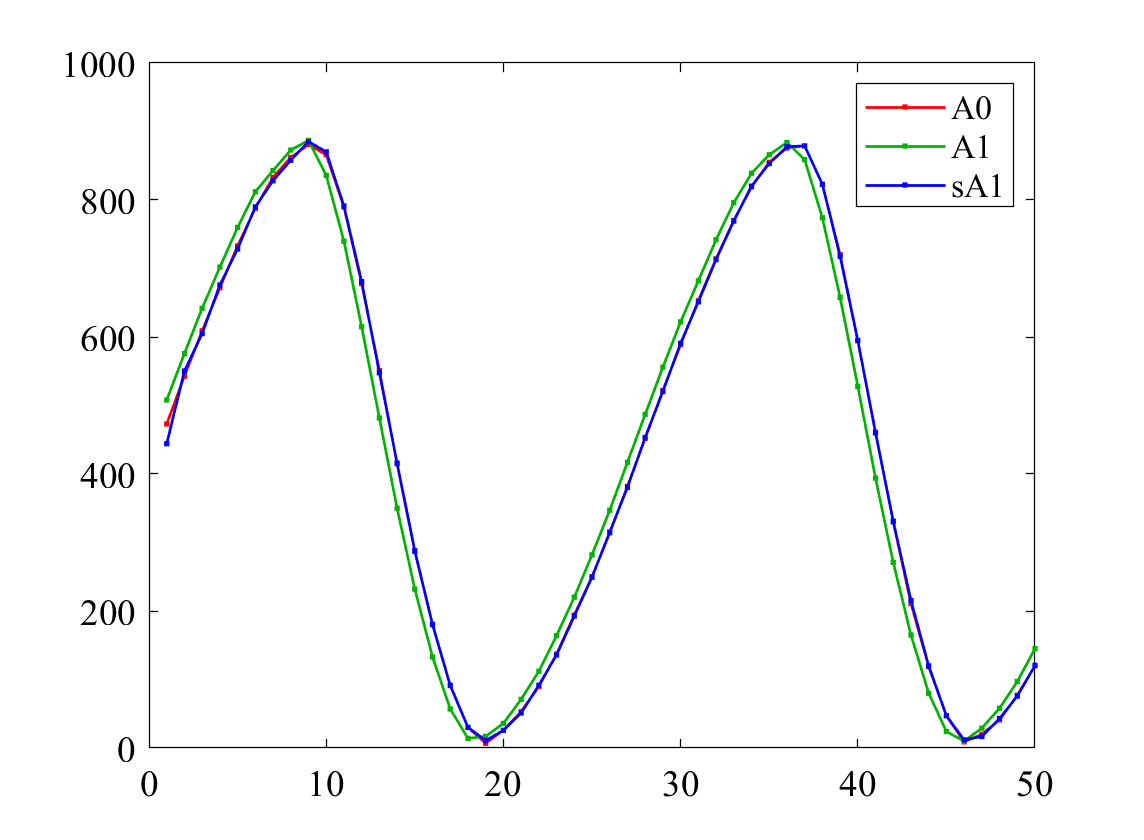

        Fig. 3. First 50 samples of Arduino data. The output of `arddeskew()` of A1 mostly is sitting right on top of A0 -- it worked.

To explore  the performance differences between time and freqeuncy domain deskewing, I rewrote the function to do both. Also added a tweak to the spline code to fix a frequent error at high frequencies, where the first data point was sometimes excessively negative (I think because there is no data point to its left to balance the spline).    

## Putting it together

and attach the callback to the runBtn: 

runBtn.Callback = 'oscope3';

### Adding a GUI

Keeping code simple is important, but simplicity in one place can hide complexity in another. The interface for `arddeskew` above -- which algorithm it is using -- is buried (hidden) inside `oscope3` code. We can do much better by making the algorithm both visible and changeable. Let's add another GUI element to the figure. Insert this code in the `runBtn` initialization block: 

That adds a popup menu visible at the the bottom of the figure window, which lets us select from 3 string choices. But can you think of how to make it *do *what we want? .... Hint: can you do it without adding *any* new lines of code?  .... 

Not many programming languages can do this much with so little code!

## Results

[need to update figures with skewCtl button]

### Comparison of spline and Fourier deskewing at one frequency

A difference plot displays the errors between A0 and A1, and rms represents the error as a scalar. I've been using a different frequency than Fig. 6, so let's compare at the deskewing methods at the current frequency, and then we'll sweep across frequencies to explore if the algorthms behave differently. 

ans =

    0.6026    0.6570   18.3613

ans =

    0.5970    0.6395   18.3337

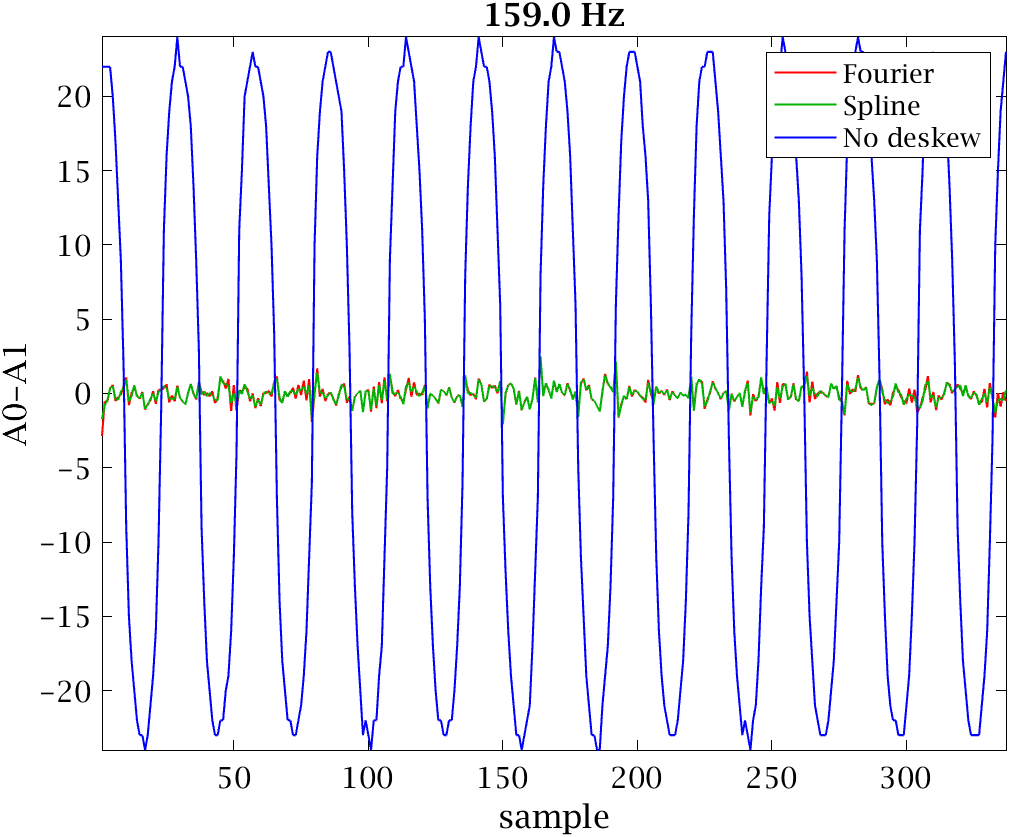

        Figure 4. Difference plots. Both deskewing algorithms are very effective.

### Difference plots and rms differences.

Deskewing reduced the inter-channel error by >20 fold (and more at higher frequencies). The time domain spline had slightly lower error than frequency domain deskewing (columns 1 and 2 of `ans` above), the second row  dropping the end points (where artifacts are greater), compared to 36 ADU of error without deskewing.

Since we empirically see spline working better, and its simpler (and doesn't require `trim()`), let's use it. We could toss (many hours of hard work on) the Fourier algorithm. But does spline beat Fourier at all frequencies?

### Comparison of spline and Fourier deskewing at many frequencies

If you've implemented Arduino control of the function generator frequency, you could fully automate sweeping by looping over a range of PWM values or frequencies. But I'm going to manually turn the frequency pot while the data is collected "open loop". Start by preallocating storage for data. `oscope3` is configured now to call `arddeskew(rdata,'f')` so to compare with the spline algorithm, we'll have call `arddeskew` again for the same data:

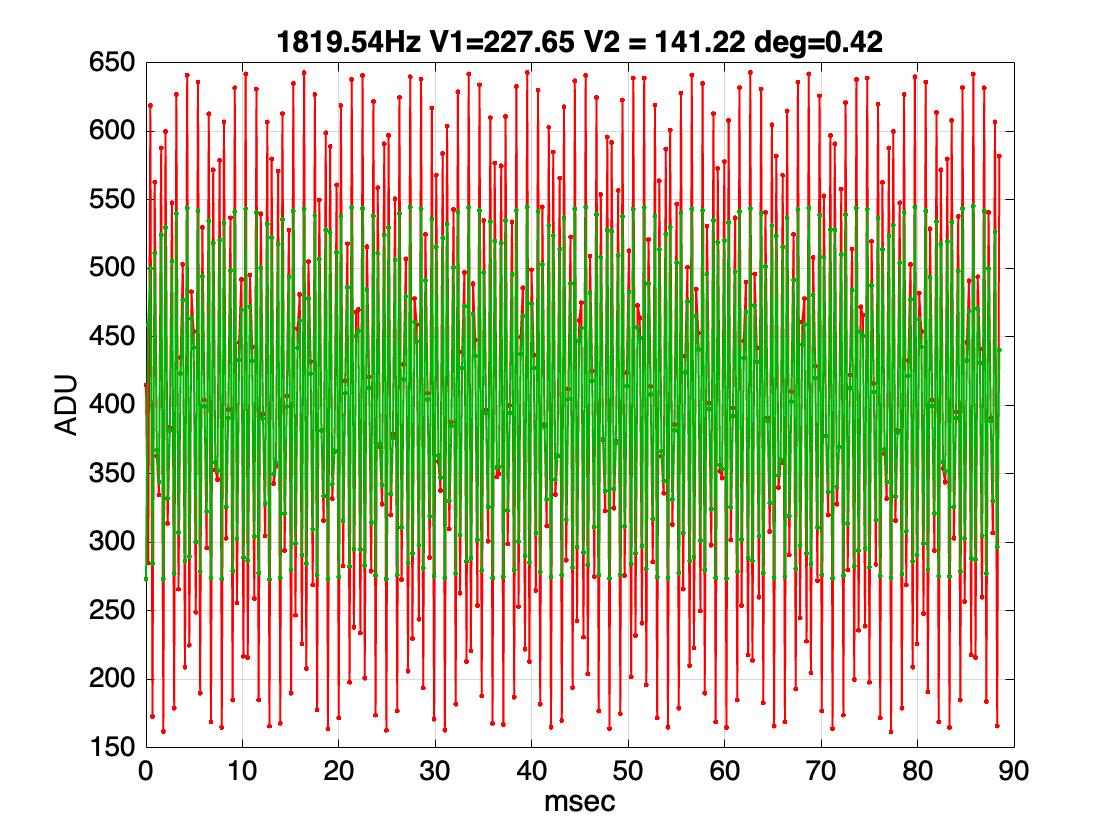

numFreqs = 50;
freqs = zeros(numFreqs, 1);
errt = freqs; % storage for rms(A0-sA1spline)
errf = freqs; % storage for rms(A0-sA1Fourier)
errn = freqs; % storage for rms(A0-A1) -- no deskew
for i = 1:numFreqs
    pause(.2); 
    runOnce = true; oscope3;
    freqs(i) = freq;
    sdata = arddeskew(rdata,'spline');
    errt(i) = rms(diff(sdata(2:end-1,:)'));
    errf(i) = rms(diff(data(2:end-1,:)'));
    errn(i) = rms(diff(rdata(2:end-1,:)'));
end 

plot(freqs, [errt errf errn],'.-'); grid; 
xlabel('Hz'); ylabel('rms error (ADU)');
legend('Spline','Fourier','no deskew','Location',"best")

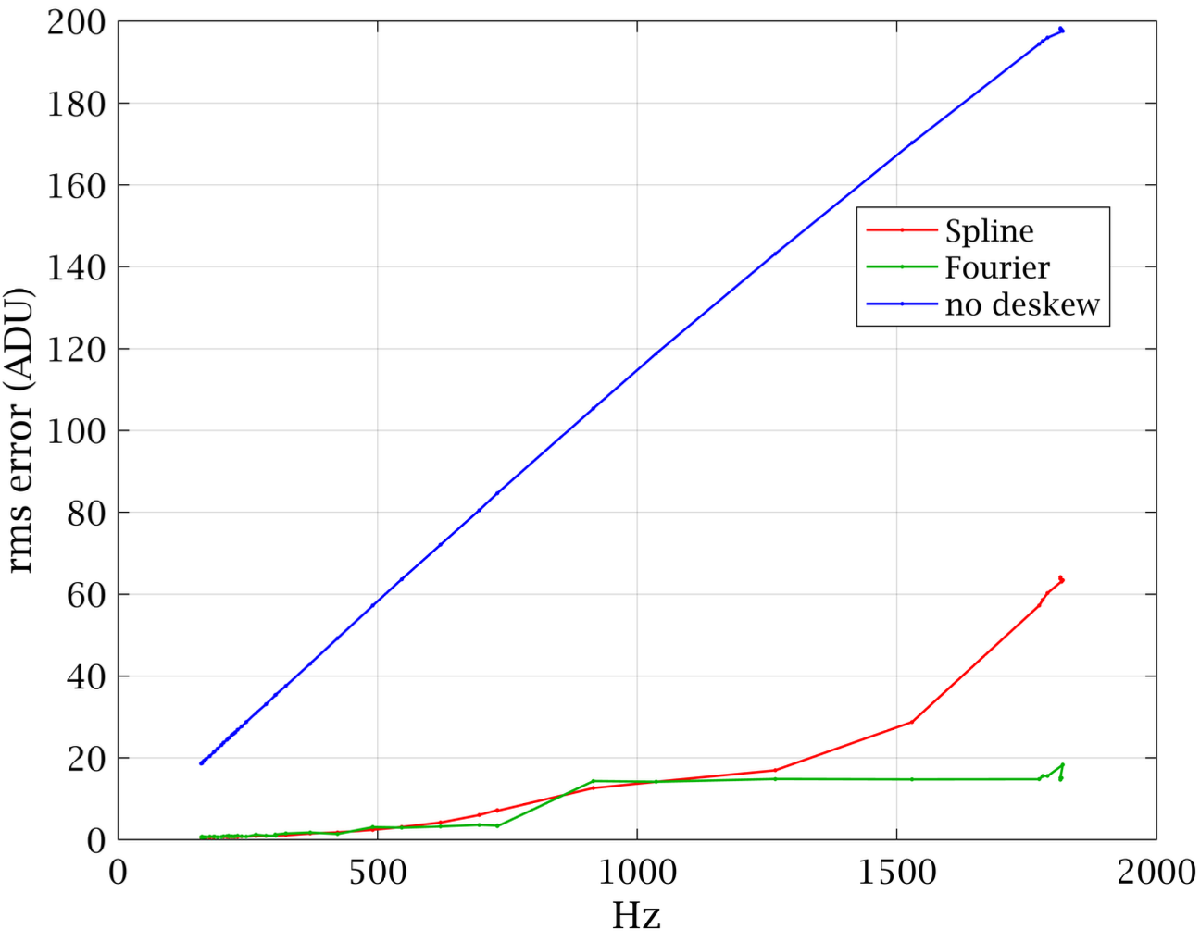

       Fig. 5. A0-A1 errors vs. frequency. 

Not surprising, no deskewing is a disaster above a few Hz and error increases linearly with frequency. Both deskewing algorithms are remarkably effective (and similar) at low frequencies, but the spline error increases linearly with frequency >~1500Hz, while the frequency domain algorithm doesn't. Not shown, but had I taken the frequency above  half the sample rate

sr/2

ans = 2.2320e+03

~2.2kHz = "Nyquist Frequency" [2], then aliasing [3] would have occured introducing multiple artifacts. Before diving into that rabbit hole, let's zoom into Fig. 5 to further quantify the errors: 

semilogy(freqs, [errt errf errn],'.-'); grid; 
xlabel('Hz'); ylabel('rms error (ADU)');
legend('Spline','Fourier','no deskew','Location',"best")

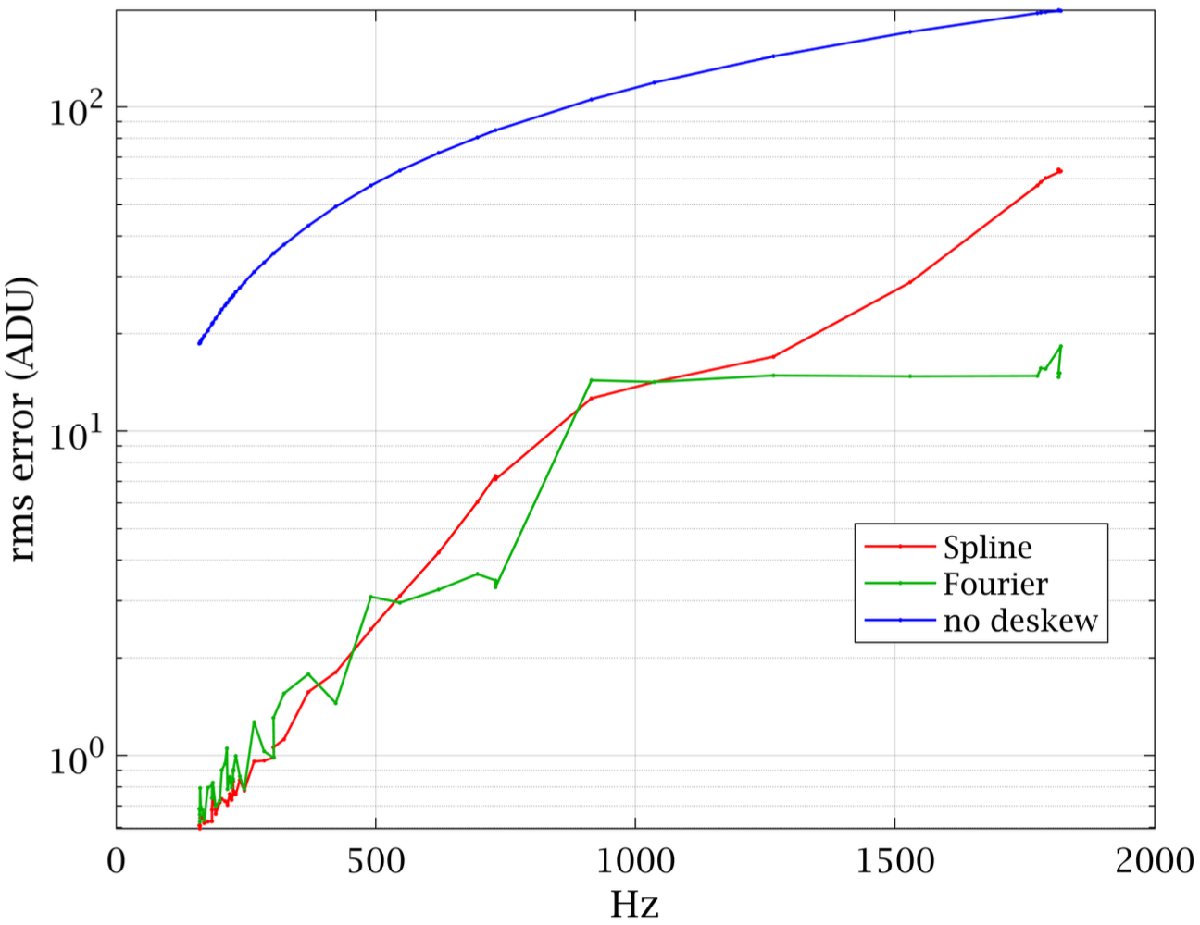

        Fig. 6.  A0-A1 errors vs. frequency on a semilog plot.

It seems consistent that at the lowest frequencies, the spline outperforms the frequency domain. There are probably two factors explaining this: 1) the polynomial data is very smooth, and 2) there are few periods of data in the 400 samples for the `fft` to average over. But as the frequency increases both these factors shift in favor of the frequency domain algorithm.

## Discussion

The Arduino Nano's analog data acquisition system is remarkably powerful especially considering this device's cost. In previous experiments we showed it can rapidly generate component I-V curve characteristics and transistor $h_{fe} = \beta$ curves with quality indistinguishable from data sheet publications. Here we've applied the Arduino to emulate a 2-channel oscilloscope, and in this dynamic regime, the Arduino is more challenged. 

Temporal skew didn't manifest itself earlier because our prior experiments measuring I-V curves and transistor hfe characteristics involved only low frequencies near DC. Many other tasks such as measuring temperature or other slowly changing parameters won't suffer from temporal skew as long as there is adequate `delay()` or `pause()` following voltage changes, thus letting higher frequency transients decay. 

Subtracting (and related differentiation) amplify noise in data. For example, if two similar signals, $x$ and $y$ are measured with 1% uncertainty (i.e., $|\Delta x/x| = |\Delta y/y| = 1\%$), then their difference $d = x-y$  will have uncertainty much higher than 1%. Even if $<y> = 0$, the uncertainty of y doesn't vanish and $|\Delta d/d| = \sqrt{(\Delta x/x)^2+(\Delta y/y)^2} \approx 1.4\%$. But if $<y> \approx <x>$ then $<d> \approx 0$ and the uncertainty explodes. This argument applies to the *random noise* in the data, which is what's left after removing the *systematic errors *as `arddeskew()` did. Usually the best way to compute a difference between signals is to do the subtraction in hardware with an instrumentation amp [4] or other differential amplifier [5]. One of the key characteristics that predicts the resulting noise is called the "common mode rejection ration" or CMMR [6]. 

At the start of the semester we characterized 2-terminal devices by computing Thevenin resistances and measuring I-V curves. Here we've taken essentially the same approach a step further in complexity, by characterizing the Arduino Nano as a 2 channel data acquisition system. Empirical testing of ones apparatus is important throughout your scientific and engineering careers. Trust nothing ... if it hasn't been validated. That applies just as well to expensive devices. The reason I would buy an expensive device is to push it to its operational extremes, so validation is never optional. The exercises we've done in the past two units exemplify the kinds of (automated) testing that gives you confidence in your apparatus. Testing and validation often include lots of little tricks. E.g., sticking `dt` at the end of the analog data array, and then reconstructing a 32 bit integer from 2 16 bit ints, or the wonky indexing games to find the right Fourier amplitude and do the phase shifts with the proper symmetry. Those "tricks" get buried in code, covered in layers of abstraction, like an onion, so you don't have to think about them when you work at "higher" levels. 

**Question.** What are the most interesting lessons and questions you got from this activity?

## References

[1] [https://en.wikipedia.org/wiki/Phasor](https://en.wikipedia.org/wiki/Phasor) (Historical note: phasors were introduced to visualize phase relationships in AC circuits in 1894 by C.P. Steinmetz.)

[2] [https://en.wikipedia.org/wiki/Nyquist_frequency](https://en.wikipedia.org/wiki/Nyquist_frequency)

[3] [https://en.wikipedia.org/wiki/Aliasing](https://en.wikipedia.org/wiki/Aliasing)

[4] [https://en.wikipedia.org/wiki/Instrumentation_amplifier](https://en.wikipedia.org/wiki/Instrumentation_amplifier) 

[5] [https://en.wikipedia.org/wiki/Differential_amplifier](https://en.wikipedia.org/wiki/Differential_amplifier) 

[6] [https://en.wikipedia.org/wiki/Common-mode_rejection_ratio](https://en.wikipedia.org/wiki/Common-mode_rejection_ratio) 